%% train_cars_kaggle_release.m
% Public-ready script to train a regression model that predicts car price
% using a frozen network (two fixed tanh FC blocks) similar to the MNIST script.
%
% Dataset
% -------
% Source: Kaggle dataset by ciyakhan: "carsdata".
% URL: https://www.kaggle.com/datasets/ciyakhan/carsdata
%
% How to download (two options):
% 1) Web UI (manual):
%    - Log in to Kaggle, open the dataset page above.
%    - Download the files (usually one or more CSVs). Put them under:
%         ./data/carsdata/
%
% 2) Kaggle CLI (recommended):
%    - Install:   pip install kaggle
%    - Create API token from Kaggle > Account > Create New API Token
%      This downloads kaggle.json; move it to ~/.kaggle/kaggle.json and
%      chmod 600 ~/.kaggle/kaggle.json (Linux/macOS). On Windows, place it
%      in C:\Users\<you>\.kaggle\kaggle.json.
%    - Then run from a shell in the repo root:
%        kaggle datasets download -d ciyakhan/carsdata -p ./data/carsdata --unzip
%    - If the dataset contains multiple CSVs, the helper below will pick a
%      suitable one or you can pass a specific CSV path.
%
% Expected MAT file
% -----------------
% This script expects ./data/toyota_dataset.mat with a variable named 'data'
% arranged so that:
%   • Column 3 is the target price (numeric)
%   • All other columns are numeric features
% The helper function 'prepare_toyota_mat_from_kaggle' (included below)
% builds this MAT file from the Kaggle CSV by:
%   • Filtering rows to Toyota if a make/brand column exists (optional)
%   • Coercing the price column to numeric
%   • Selecting numeric features only
%   • Reordering columns so that PRICE is the 3rd column (to match this
%     training script's original interface)
%
% Usage
% -----
% 1) If you don't already have ./data/toyota_dataset.mat, run in MATLAB:
%       prepare_toyota_mat_from_kaggle('./data/carsdata', './data/toyota_dataset.mat');
% 2) Then run this file:
%       train_cars_kaggle_release
%
% Notes
% -----
% * Requires: MATLAB R2023b+ and Deep Learning Toolbox.
% * Custom initializers: we use your original functions
%     customWeights1_git / customWeights2_git / customWeights3_git
%   Ensure these are on the MATLAB path (same folder or +package).
% * Plots: we keep the built-in training progress window and generate extra
%   result plots on the test set (parity, residuals histogram, residuals vs
%   fitted, and calibration) which are saved under ./results.

%% -------------------- User-configurable section --------------------
RESULTS_DIR = './';
DATA_DIR    = './';
MAT_PATH    = fullfile(DATA_DIR, 'toyota_dataset.mat');
WIDTH       = 16000;     % reduce (e.g., 4096) if memory-constrained
MAX_EPOCHS  = 10000;
LR          = 0.01;
BATCH_CAP   = 4096;      % cap for minibatch size

%% -------------------------- Main routine --------------------------
clearvars -except RESULTS_DIR DATA_DIR MAT_PATH WIDTH MAX_EPOCHS LR BATCH_CAP
close all; clc; rng(42,'twister');
if ~exist(RESULTS_DIR,'dir'); mkdir(RESULTS_DIR); end

% Build the MAT file if missing
if ~isfile(MAT_PATH)
    warning('MAT file not found at %s. Attempting to create it from CSVs...', MAT_PATH);
    prepare_toyota_mat_from_kaggle(fullfile(DATA_DIR,'carsdata'), MAT_PATH);
end

% Load numeric matrix 'data' and construct features/targets
S = load(MAT_PATH);
assert(isfield(S,'data'), 'MAT must contain variable ''data'' (numeric matrix).');
data = S.data; data(isnan(data)) = 0;

% Target price is column 3, as per original script
price = data(:,3);

% Features are all columns except the 3rd (keep original indexing style)
X = data(:, [1,2,4:end])';   % features as [C x N]

% Normalize features: zero-mean / unit-std per channel, scaled by 1/sqrt(C)
muX = mean(X,2); sigX = std(X,0,2); sigX(sigX==0) = 1;  % avoid divide-by-zero
X = (1/sqrt(size(X,1))) * ((X - muX) ./ sigX);

% Train/val/test split
numSamples = size(X,2);
cv = cvpartition(numSamples, 'HoldOut', 0.2);
XTrainFull = X(:, training(cv));   YTrainFull = price(training(cv));
XTest      = X(:, test(cv));       YTest      = price(test(cv));

cvVal = cvpartition(size(XTrainFull,2), 'HoldOut', 0.2);
XTrain = XTrainFull(:, training(cvVal));  YTrain = YTrainFull(training(cvVal));
XVal   = XTrainFull(:, test(cvVal));      YVal   = YTrainFull(test(cvVal));

% Normalize targets using training stats
Ymu = mean(YTrain); Ystd = std(YTrain); if Ystd==0, Ystd=1; end
YTrainN = (YTrain - Ymu) / Ystd;   YValN = (YVal - Ymu) / Ystd;


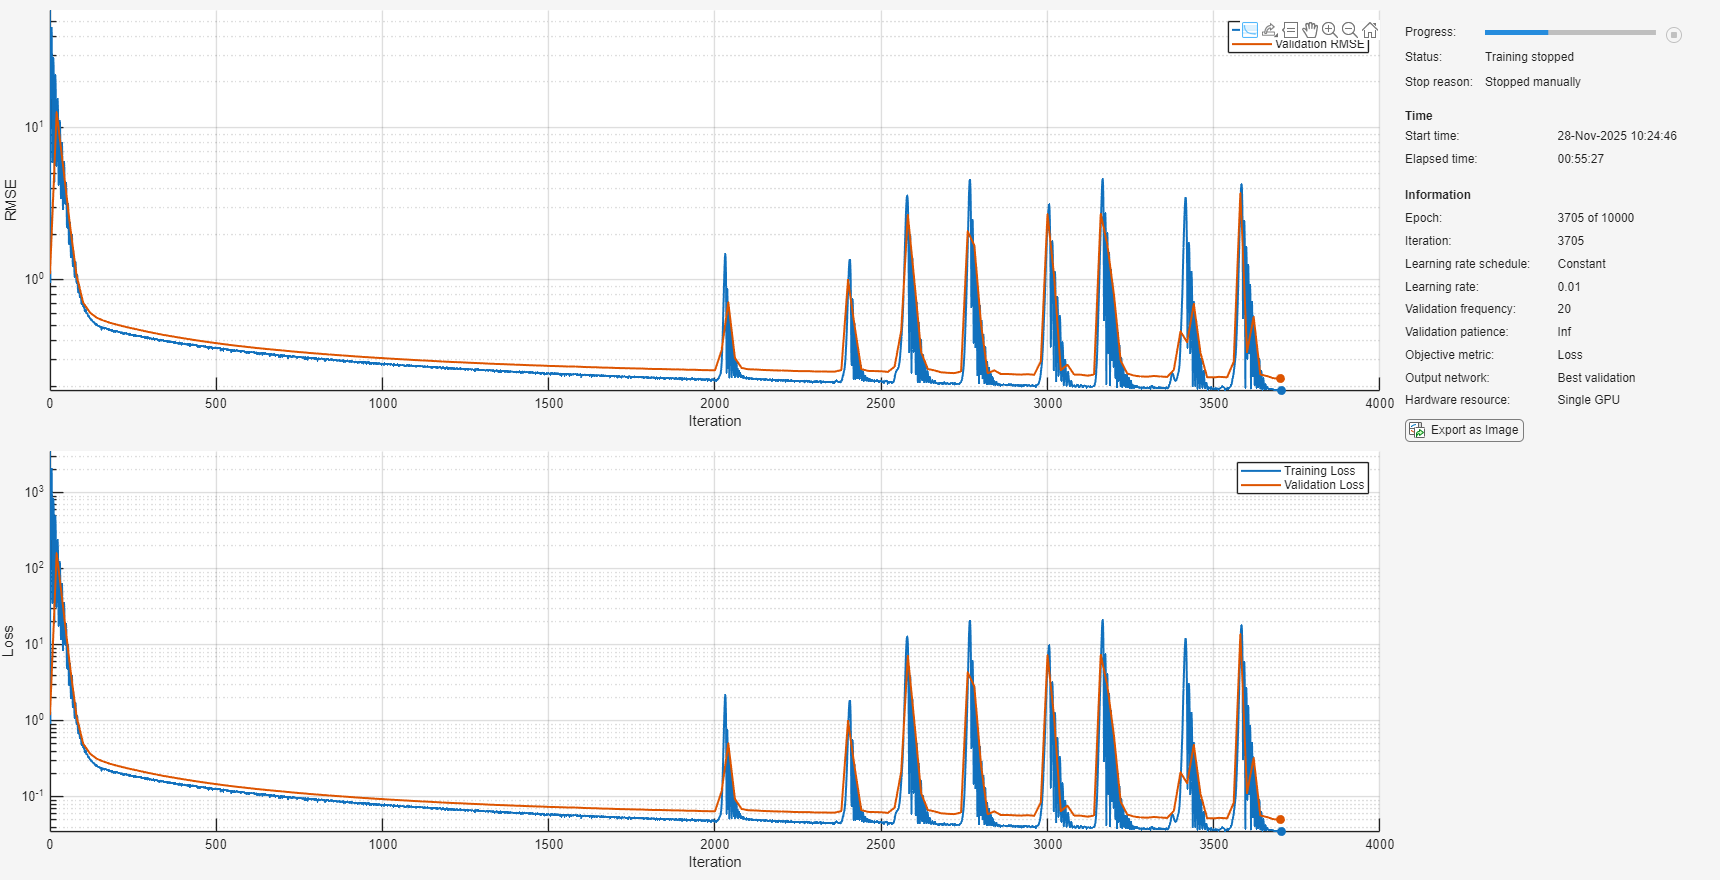

% Network: two frozen tanh blocks + trainable linear head
layers = [
    featureInputLayer(size(XTrain,1), Normalization='none')
    fullyConnectedLayer(WIDTH, 'WeightLearnRateFactor',0, ...
        'WeightsInitializer',@customWeights1_git, 'BiasL2Factor',0, 'BiasInitializer','zeros')
    tanhLayer
    fullyConnectedLayer(WIDTH, 'WeightLearnRateFactor',0, ...
        'WeightsInitializer',@customWeights2_git, 'BiasL2Factor',0, 'BiasInitializer','zeros')
    tanhLayer
    fullyConnectedLayer(1, 'Name','output', 'WeightLearnRateFactor',1, ...
        'WeightsInitializer',@customWeights3_git, 'BiasL2Factor',0, 'BiasInitializer','zeros')
    ];

net = dlnetwork(layers);

% Convert to dlarray (channels-batch)
XTrain_dl = dlarray(single(XTrain), 'CB');
XVal_dl   = dlarray(single(XVal),   'CB');

miniB = min(BATCH_CAP, size(XTrain,2));
opts = trainingOptions('adam', ...
    'MaxEpochs', MAX_EPOCHS, ...
    'Metrics',  ["rmse"], ...
    'MiniBatchSize', miniB, ...
    'InitialLearnRate', LR, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XVal_dl, YValN}, ...
    'ValidationFrequency', 20, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment','auto', ...
    'Verbose', false);

[net, info] = trainnet(XTrain_dl, YTrainN, net, 'mse', opts); %#ok<NASGU>

% Test-time inference
XTest_dl = dlarray(single(XTest), 'CB');
YpredN = predict(net, XTest_dl);
Ypred  = double(gather(extractdata(YpredN)))*Ystd + Ymu;  % back to original scale
Ypred  = Ypred(:);
Ytrue  = double(YTest(:));

% ------------------------ Metrics (robust types + Pearson r) ------------------------
% Ensure numeric CPU doubles (handles dlarray/gpuArray safely)
YpredNum = Ypred;
if isa(YpredNum,'dlarray'),  YpredNum = extractdata(YpredNum); end
if isa(YpredNum,'gpuArray'), YpredNum = gather(YpredNum); end
YpredNum = double(YpredNum(:));

YtrueNum = Ytrue;
if isa(YtrueNum,'dlarray'),  YtrueNum = extractdata(YtrueNum); end
if isa(YtrueNum,'gpuArray'), YtrueNum = gather(YtrueNum); end
YtrueNum = double(YtrueNum(:));

% Common finite mask (apply to everything consistently)
m = isfinite(YpredNum) & isfinite(YtrueNum);
YpredNum = YpredNum(m);
YtrueNum = YtrueNum(m);

% Signed error: prediction - truth (positive = over-predict)
err = YpredNum - YtrueNum;

% Core metrics
MAE   = mean(abs(err));
MedAE = median(abs(err));
RMSE  = sqrt(mean(err.^2));

% Signed bias stats
errMean = mean(err);
errStd  = std(err, 0);

% R^2 (use truth mean; guard degenerate variance)
den = sum((YtrueNum - mean(YtrueNum)).^2);
num = sum((YtrueNum - YpredNum).^2);
if den > 0
    R2 = 1 - num/den;
else
    R2 = NaN;
end

% sMAPE (robust; eps protects division)
SMAPE = 100*mean(2*abs(YpredNum - YtrueNum) ./ (abs(YpredNum) + abs(YtrueNum) + eps));

% Pearson correlation (pred vs true)
if numel(YtrueNum) >= 2 && std(YtrueNum) > 0 && std(YpredNum) > 0
    [rPearson, pPearson] = corr(YpredNum, YtrueNum, 'Type','Pearson', 'Rows','complete');
else
    rPearson = NaN; pPearson = NaN;
end

fprintf(['Test metrics: MAE=%.4g, MedAE=%.4g, RMSE=%.4g, R^2=%.4f, sMAPE=%.2f%% | ' ...
         'Signed err mean=%.4g, sd=%.4g | Pearson r=%.4f (p=%.3g)\n'], ...
    MAE, MedAE, RMSE, R2, SMAPE, errMean, errStd, rPearson, pPearson);

Test metrics: MAE=895.5, MedAE=633.1, RMSE=1283, R^2=0.9595, sMAPE=7.50% | Signed err mean=-24.42, sd=1283 | Pearson r=0.9797 (p=0)


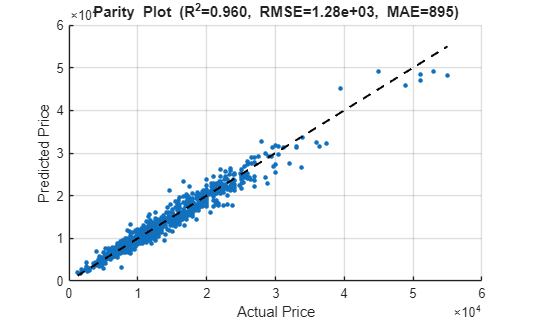

% ------------------------ NICE RESULT PLOTS ------------------------
% 1) Parity (Predicted vs Actual)
fig1 = figure('Name','Parity: Predicted vs Actual','Color','w');
scatter(Ytrue, Ypred, 12, 'filled'); hold on; grid on;
lims = [min([Ytrue(:); Ypred(:)]) max([Ytrue(:); Ypred(:)])]; if ~isfinite(lims), lims=[0 1]; end
plot(lims, lims, 'k--','LineWidth',1.5);
xlabel('Actual Price'); ylabel('Predicted Price');
title(sprintf('Parity Plot (R^2=%.3f, RMSE=%.3g, MAE=%.3g)', R2, RMSE, MAE));

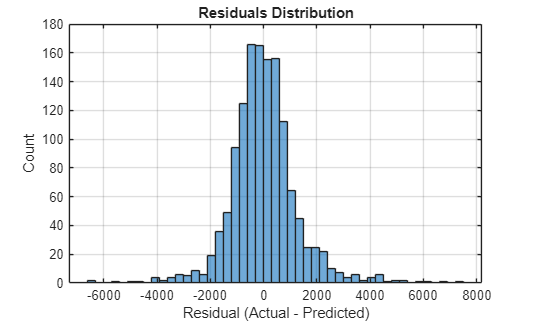


% 2) Residuals histogram
fig2 = figure('Name','Residuals Histogram','Color','w');
histogram(res, 'BinMethod','fd'); grid on;
xlabel('Residual (Actual - Predicted)'); ylabel('Count');
title('Residuals Distribution');

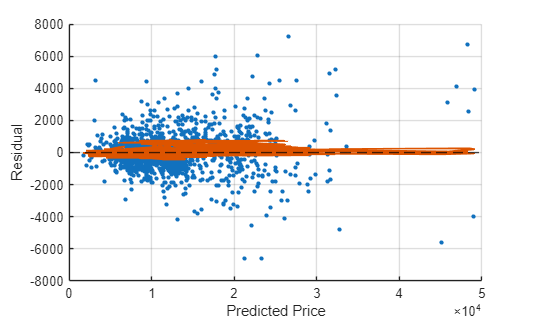



% 3) Residuals vs Fitted
fig3 = figure('Name','Residuals vs Fitted','Color','w');
scatter(Ypred, res, 10, 'filled'); hold on; grid on;
xlabel('Predicted Price'); ylabel('Residual'); yline(0,'k--');
try
    sm = smoothdata(res, 'movmedian', max(5, round(0.05*numel(res))));
    plot(Ypred, sm, 'LineWidth',1.5);
end

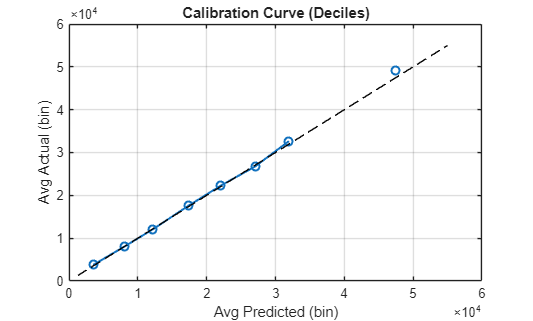



% 4) Calibration (binned)
fig4 = figure('Name','Calibration (Binned)','Color','w');
nb = 10; [~,~,bin] = histcounts(Ypred(:), nb);
calX = zeros(nb,1); calY = zeros(nb,1);
for b=1:nb
    idx = (bin==b);
    if any(idx)
        calX(b) = mean(Ypred(idx));
        calY(b) = mean(Ytrue(idx));
    else
        calX(b) = NaN; calY(b) = NaN;
    end
end
plot(calX, calY, 'o-', 'LineWidth',1.5); hold on; grid on;
plot(lims, lims, 'k--');
xlabel('Avg Predicted (bin)'); ylabel('Avg Actual (bin)');
title('Calibration Curve (Deciles)');

%% ------------------------ Helper functions ------------------------
function prepare_toyota_mat_from_kaggle(inDirOrCsv, outMat)
% Prepare ./data/toyota_dataset.mat from a Kaggle CSV directory or a CSV.
%  - Detects a CSV in a directory (picks the largest one if multiple)
%  - Attempts to find a price column by common name patterns
%  - Filters to Toyota rows if a make/brand column exists (optional)
%  - Keeps numeric features only, coerces price to numeric if necessary
%  - Reorders columns so that PRICE is the 3rd column
%
% Example usage:
%   prepare_toyota_mat_from_kaggle('./data/carsdata','./data/toyota_dataset.mat')

    if isfolder(inDirOrCsv)
        d = dir(fullfile(inDirOrCsv,'*.csv'));
        assert(~isempty(d), 'No CSV files found in %s', inDirOrCsv);
        [~,idx] = max([d.bytes]);
        csvPath = fullfile(d(idx).folder, d(idx).name);
    else
        csvPath = inDirOrCsv;
    end
    assert(isfile(csvPath), 'CSV not found: %s', csvPath);

    T = readtable(csvPath, 'TextType','string');

    % Try to filter to Toyota if a make/brand column exists
    mk = findVar(T, ["make","brand","company","manufacturer","car_make","car_brand"]);
    if ~isempty(mk)
        keep = strcmpi(strtrim(T.(mk)), 'Toyota');
        if any(keep)
            T = T(keep,:);
        end
    end

    % Identify a price column (case-insensitive search over common names)
    priceVar = findVar(T, ["price","selling_price","msrp","saleprice","price_usd","priceusd"]);
    assert(~isempty(priceVar), 'Could not locate a price column in %s', csvPath);

    % Coerce price to numeric (strip currency symbols/commas)
    if ~isnumeric(T.(priceVar))
        s = string(T.(priceVar));
        s = regexprep(s, '[^0-9\.-]', '');
        p = double(str2double(s));
    else
        p = double(T.(priceVar));
    end

    % Keep numeric predictors (exclude the price column itself)
    isNum = varfun(@isnumeric, T, 'OutputFormat','uniform');
    numVars = T(:, isNum);
    if ismember(priceVar, numVars.Properties.VariableNames)
        numVars.(priceVar) = [];
    end

    % Assemble matrix: [firstTwoNumeric price restNumeric]
    Xnum = table2array(numVars);
    if isempty(Xnum)
        error('No numeric predictor columns found after filtering.');
    end
    k = min(2, size(Xnum,2));
    left = Xnum(:, 1:k);
    right = Xnum(:, k+1:end);
    data = [left, p(:), right]; %#ok<NASGU>

    save(outMat, 'data', '-v7.3');
    fprintf('Wrote %s (rows=%d, cols=%d; price at col 3)\n', outMat, size(data,1), size(data,2));
end

function name = findVar(T, candidates)
% Return the first matching variable name in table T from candidate list.
    vars = string(T.Properties.VariableNames);
    name = "";
    for c = candidates
        idx = find(strcmpi(vars, c), 1);
        if ~isempty(idx)
            name = vars(idx); break;
        end
    end
    name = char(name);
end
